hcData = load('Debye/Cp.txt');
T = hcData(:, 1);  % Temperature in K
C_exp = hcData(:, 2);      % Cp in J/Kmol per Gd5Pbb3 #8 atoms
%% Set Temperature Cutoff
T_cutoff = 300; % Change this value to set the maximum temperature for fitting

% Filter Data: Keep only points where T <= T_cutoff
valid_idx = T <= T_cutoff;
T = T(valid_idx);
C_exp = C_exp(valid_idx);

%constants
R = 8.314 % Gas constant (J/mol·K)

R = 8.3140

a = 8 %number of atoms

a = 8

debye_integral = @(x) (x.^4 .* exp(x)) ./ ((exp(x) - 1).^2);
debye_model = @(params, T) arrayfun(@(t) compute_debye_C(t, params(1), params(2), debye_integral, R, a), T);

% Function to compute specific heat for given T and parameters
function C = compute_debye_C(T, theta_D, debye_integral, R, a)
    % Numerical integration of Debye function
    integral_value = integral(@(x) debye_integral(x), 0, theta_D/T, 'ArrayValued', true);
    C = 9 * R * a* (T/theta_D)^3 * integral_value;
end

debye_model_scalar = @(theta_D, T) arrayfun(@(t) compute_debye_C(t, theta_D, debye_integral, R, a), T);
% Define custom fit type
fit_type = fittype(@(theta_D, T) debye_model_scalar(theta_D, T), ...
    'independent', 'T', 'coefficients', {'theta_D'});

% Initial guesses
theta_D_guess = 300; % Initial guess for theta_D0

% Fit model to data
fit_result = fit(T, C_exp, fit_type, 'StartPoint', theta_D_guess);

% Extract fitted parameters
theta_D_fitted = fit_result.theta_D;

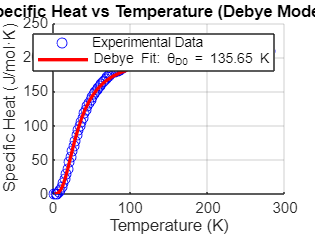

%% Plot Data and Fitted Model
figure;
scatter(T, C_exp, 'bo', 'DisplayName', 'Experimental Data'); hold on;
plot(T, feval(fit_result, T), 'r-', 'LineWidth', 2, 'DisplayName', ...
    sprintf('Debye Fit: θ_{D0} = %.2f K', theta_D_fitted));
xlabel('Temperature (K)');
ylabel('Specific Heat (J/mol·K)');
title('Specific Heat vs Temperature (Debye Model Fit)');
legend;
grid on;